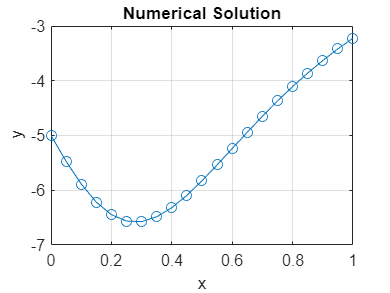

x0 = 0;
y0 = -5;
a = 0;
b = 1;
h = 0.05;
y = Euler_Implicit(@f, y0, a, b, h);

x = linspace(a, b, length(y));
plot(x, y, '-o');
xlabel('x');
ylabel('y');
title('Numerical Solution');
grid on;

function y = Euler_Implicit(f, y0, a, b, h)
    n = round((b-a)/h);
    y = zeros(1, n+1);
    y(1) = y0;
    
    for i = 2:n+1
        xi = a + (i-1) * h;
        yi = y(i-1);
        for j = 1:100
            yi = y(i-1) + h * f(xi, yi);
        end
        y(i) = yi;
    end
end

function fullderi = f(x, y)
    fullderi = x*y^2 + 2*y;
end


